HCPex = MRI_read_Data([HCPex_root,'HCPex.nii']);

sMRI [229,193,193] res:[1,1,1]


temp = readtable([HCPex_root,'HCPex_LookUpTable.lut'],'FileType',"delimitedtext");
HCPcmap = table(); HCPcmap.id = temp{:,1}; HCPcmap.rgb = temp{:,2:4}; HCPcmap.name = temp{:,5}; HCPcmap.hemi = temp{:,6};

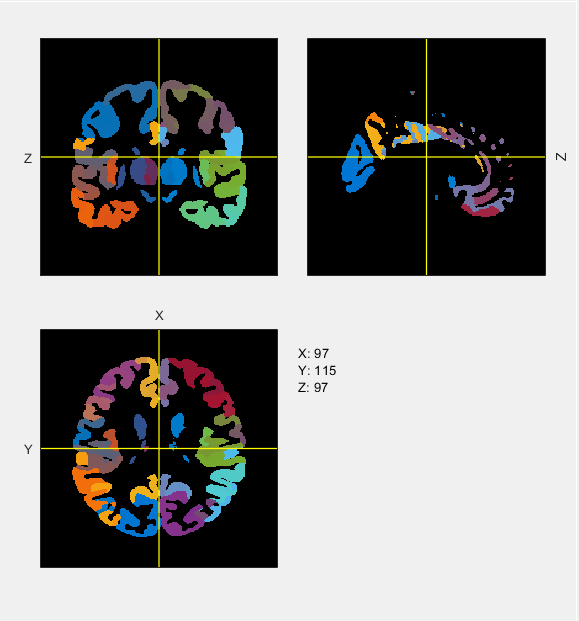

plot_mri(HCPex)
cmap_disc = [0,0,0; mat_cut(imresize(lines(8),[426,3]),0,1)];
colormap(cmap_disc)

# load mni files

t_tic = tic;
save_dir = 'E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\';
disp_paths(save_dir)

    1: E:\work_Code\Matlab\ZYS\DIY_App\SEEG_Mapper\Atlas\HCPex\surfer_zys\    



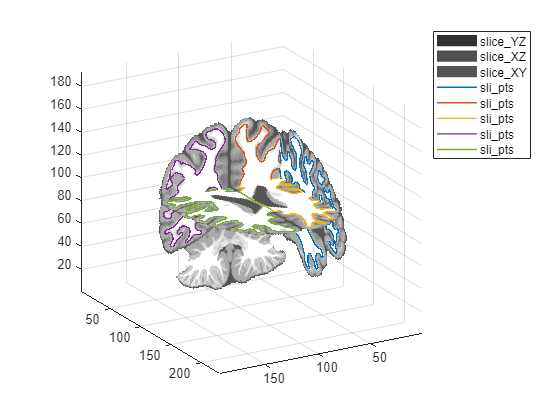


mniL_pialL_bin2 = Surf_read_Data([save_dir,'mniL_pialL_bin2.~']);
mniR_pialR_bin2 = Surf_read_Data([save_dir,'mniR_pialR_bin2.~']);

cmap_FSLre = mniL_pialL_bin2.cmap_FSLre;
cmap_FSLre = [1,1,1; cmap_FSLre];

v_shift = [1,1,1];
mniL_pialL_bin2.Vertices = mniL_pialL_bin2.Vertices + v_shift;
mniR_pialR_bin2.Vertices = mniR_pialR_bin2.Vertices + v_shift;

figure;
next; slice_mri(mni_frac,[50,80,100],'add_surf',{mniL_pialL_bin2,mniR_pialR_bin2}); view(150,20)

LAB = mat_cut(mni_frac.data-1,0);
WG = LAB;
WG(WG<1) = 1;
WG = imgradient3(WG);

if 0
opts ={'attach_grad','map',WG,'d',1,'iter',12,'d_decay',1.25};
[surf_mniL,Gmean,d] = Surf_func_ROI(mniL_pialL_bin2,opts{:});
Gmean(round(linspace(1,end,10)))
[surf_mniR,Gmean,d] = Surf_func_ROI(mniR_pialR_bin2,opts{:});
Gmean(round(linspace(1,end,10)))
else
    surf_mniL = mniL_pialL_bin2;
    surf_mniR = mniR_pialR_bin2;
end

skmni = Surf_voxelise({surf_mniL,surf_mniR},'mode',0,'ref',mni_gray);

tic
skmni_fill = Surf_voxelise({surf_mniL,surf_mniR},'mode',1,'ref',mni_gray);
skmni_indist = MRI_func_ROI(skmni_fill.data==0,'dist_map');
skmni_outdist = MRI_func_ROI(skmni_fill.data==0,'dist_map','if_inv',1,'ext',-1);
skmni_dist = skmni_indist.data - skmni_outdist.data;
toc

历时 2.399701 秒。


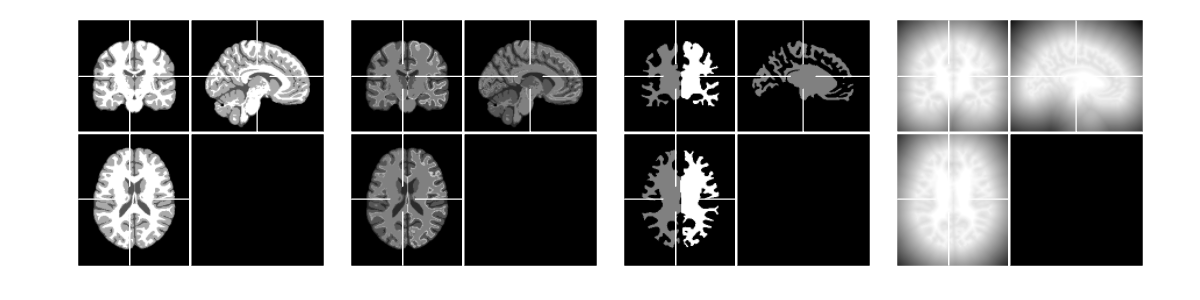


figure; lay_sub(1,4); next; plot_mri({mni_frac,skmni.data+mni_frac.data,skmni_fill,amp(skmni_dist)},'off');
lay_fig([12,3]);

inflat_sm = 1000;
surf_indL = Surf_read_Data(surf_mniL,'reset',1);
surf_indR = Surf_read_Data(surf_mniR,'reset',1);
mri_ind = LAB;
skind = skmni;

tic
surfL_warp = Surf_smooth(surf_indL,'iter',inflat_sm,'type',3);
surfR_warp = Surf_smooth(surf_indR,'iter',inflat_sm,'type',3);
toc

历时 6.532185 秒。


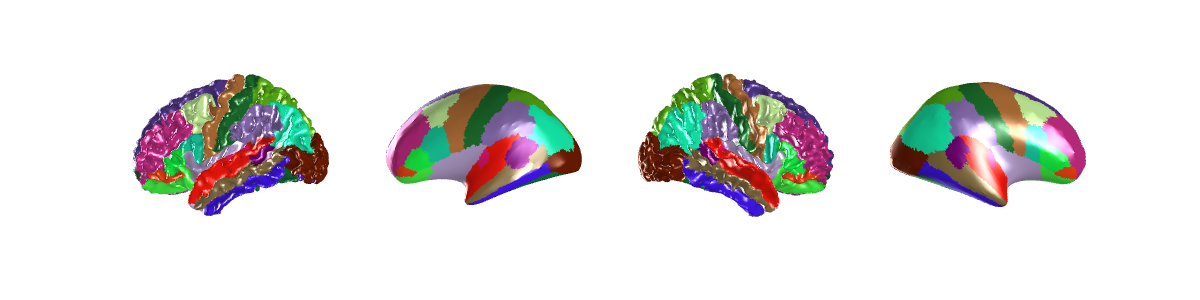


mniL_inflat = surfL_warp;
mniR_inflat = surfR_warp;

figure; colormap(cmap_FSLre); 
opts = {'colors',surf_mniL.Labels_FSL};
next; plot_surf(surf_mniL,opts{:}); view(-90,0)
next; plot_surf(surfL_warp,opts{:}); view(-90,0)
opts = {'colors',surf_mniR.Labels_FSL};
next; plot_surf(surf_mniR,opts{:}); view(90,0)
next; plot_surf(surfR_warp,opts{:}); view(90,0)
lay_fig([12,3]); lay_fig('func','legend off; axis off');

mniL_out = surf_mniL; mniL_out.Vertices = surf_mniL.VoutL+v_shift;
mniR_out = surf_mniR; mniR_out.Vertices = surf_mniR.VoutR+v_shift;

tic
mniL_outsm = Surf_smooth(mniL_out,'iter',inflat_sm,'type',3);
mniR_outsm = Surf_smooth(mniR_out,'iter',inflat_sm,'type',3);
skoutsm = Surf_voxelise({mniL_outsm,mniR_outsm},'mode',0,'ref',mri_ind);
skoutsm_fill = Surf_voxelise({mniL_outsm,mniR_outsm},'mode',1,'ref',mri_ind);
toc

历时 7.873455 秒。


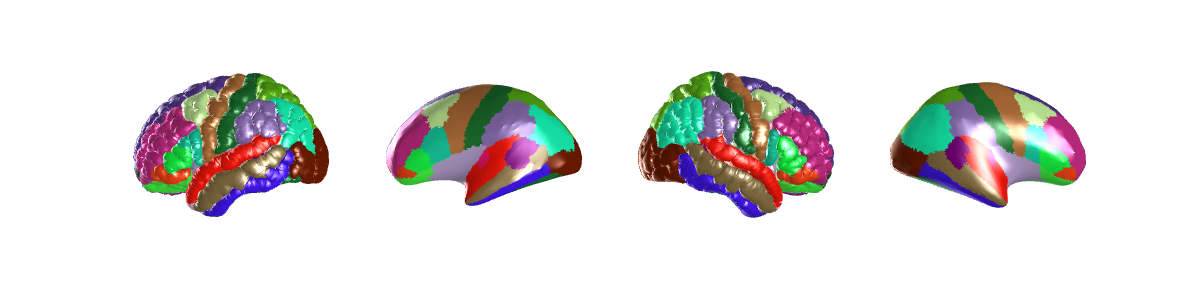


figure; colormap(cmap_FSLre); 
opts = {'colors',surf_mniL.Labels_FSL};
next; plot_surf(mniL_out,opts{:}); view(-90,0)
next; plot_surf(mniL_outsm,opts{:}); view(-90,0)
opts = {'colors',surf_mniR.Labels_FSL};
next; plot_surf(mniR_out,opts{:}); view(90,0)
next; plot_surf(mniR_outsm,opts{:}); view(90,0)
lay_fig([12,3]); lay_fig('func','legend off; axis off');

tic
temp = [];
skind_fill = Surf_voxelise({surf_indL,surf_indR},'mode',1,'ref',mri_ind);
skind_indist = MRI_func_ROI(skind_fill.data==0,'dist_map');
skind_outdist = MRI_func_ROI(skind_fill.data==0,'dist_map','if_inv',1,'ext',-1);
skind_dist = skind_indist.data - skind_outdist.data;
toc

历时 2.381566 秒。


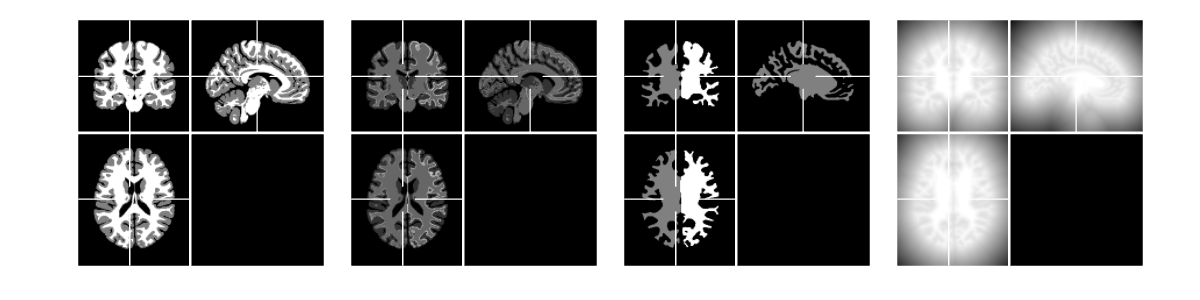


figure; lay_sub(1,4); next; plot_mri({mri_ind,mri_ind+skind.data,skind_fill,amp(skind_dist)},'off');
lay_fig([12,3]);

skind_warp = Surf_voxelise({surfL_warp,surfR_warp},'mode',0,'ref',mri_ind);
mri = mat_cut(mni_frac.data-1,0);

tic
skind_warp_fill = Surf_voxelise({surfL_warp,surfR_warp},'mode',1,'ref',mri_ind);
skind_warp_indist = MRI_func_ROI(skind_warp_fill.data==0,'dist_map');
skind_warp_outdist = MRI_func_ROI(skind_warp_fill.data==0,'dist_map','if_inv',1,'ext',-1);
skind_warp_dist = skind_warp_indist.data - skind_warp_outdist.data;
toc

历时 1.612127 秒。


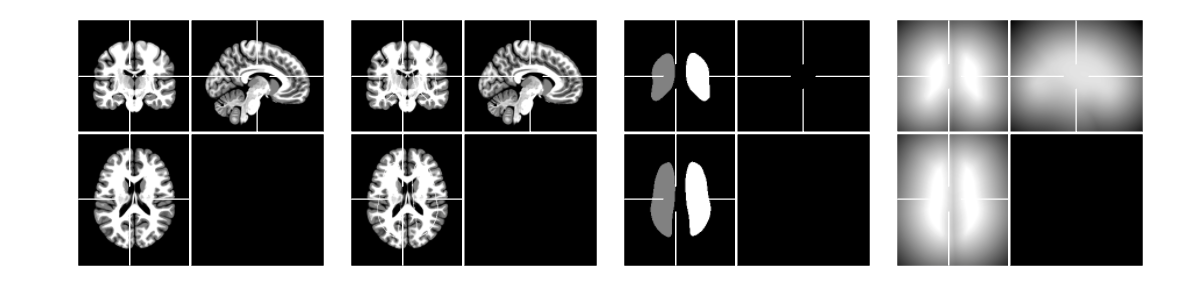


figure; lay_sub(1,4); next; plot_mri({mri,skind_warp.data+mri,skind_warp_fill,amp(skind_warp_dist)},'off','enhance',@amp);
lay_fig([12,3]);

pl_d = 8*[1,1];
pl_iter = 8;
pl_d_sm = pl_d*0.75;
smooth_surf = 2;

tic
distmap_ind = {skind_outdist,skind_indist};
% distmap_mni = {skmni_outdist,skmni_indist};
distmap_ind_warp = {skind_warp_outdist,skind_warp_indist};
surf_indL_pl = []; surf_indL_plwarp = []; d1_real = [];
for i = 1:2
    [surf_indL_pl{i},~,vL_pl_iters{i}] = Surf_func_ROI(surf_indL,'peel_distgrad','map',distmap_ind{i},'d',pl_d(i),'iter',pl_iter);
    % 由于折叠，实际peel厚度不足
    d1_real{i,1} = squeeze(vecnorm(diff(cat(3,surf_indL.Vertices,vL_pl_iters{i}),1,3),2,2));
    mean(d1_real{i,1},'all')
    [surf_indL_plwarp{i},~,vL_plwarp_iters{i}] = Surf_func_ROI(surfL_warp,'peel_distgrad','map',distmap_ind_warp{i},'d',pl_d_sm(i),'iter',pl_iter);
    d2_real{i,1} = squeeze(vecnorm(diff(cat(3,surfL_warp.Vertices,vL_plwarp_iters{i}),1,3),2,2));
    mean(d2_real{i,1},'all')
end

ans = single
      0.88968


ans =       0.74942


ans = single
      0.79553


ans =       0.74784


surf_indR_pl = []; surf_indR_plwarp = [];
for i = 1:2
    [surf_indR_pl{i},~,vR_pl_iters{i}] = Surf_func_ROI(surf_indR,'peel_distgrad','map',distmap_ind{i},'d',pl_d(i),'iter',pl_iter,'smooth_surf',smooth_surf);
    d1_real{i,2} = squeeze(vecnorm(diff(cat(3,surf_indR.Vertices,vR_pl_iters{i}),1,3),2,2));
    mean(d1_real{i,2},'all')
    [surf_indR_plwarp{i},~,vR_plwarp_iters{i}] = Surf_func_ROI(surfR_warp,'peel_distgrad','map',distmap_ind_warp{i},'d',pl_d_sm(i),'iter',pl_iter);
    d2_real{i,2} = squeeze(vecnorm(diff(cat(3,surfR_warp.Vertices,vR_plwarp_iters{i}),1,3),2,2));
    mean(d2_real{i,2},'all')
end

ans = single
      0.77767


ans =       0.74944


ans = single
      0.72841


ans =       0.74791


toc

历时 6.355103 秒。


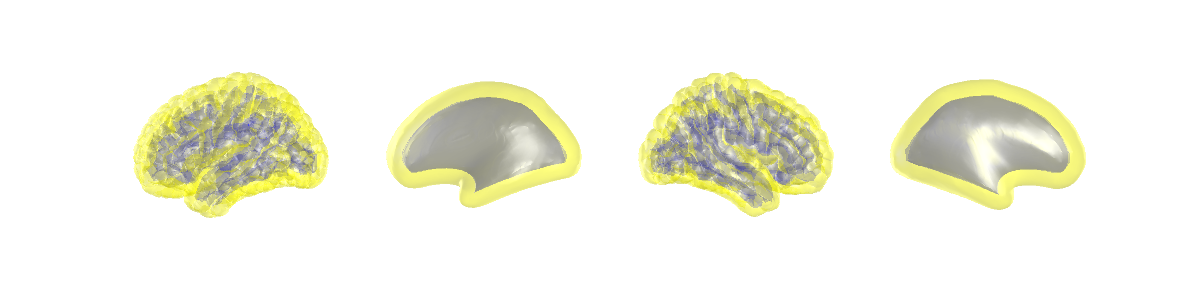


figure;
next; plot_surf(surf_indL_pl,[1,1,0; 0,0,1],0.3); view(-90,0)
next; plot_surf(surf_indL_plwarp,[1,1,0; 0,0,1],0.3); view(-90,0)
next; plot_surf(surf_indR_pl,[1,1,0; 0,0,1],0.3); view(90,0)
next; plot_surf(surf_indR_plwarp,[1,1,0; 0,0,1],0.3); view(90,0)
lay_fig([12,3]); lay_fig('func','legend off; axis off');

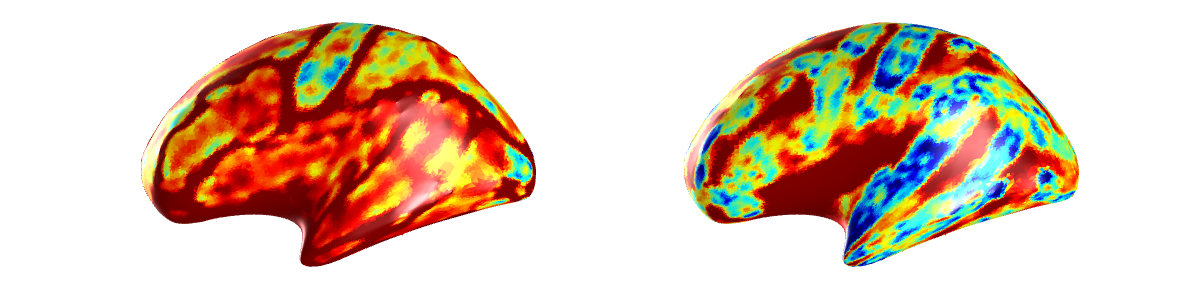

val1 = mean(d1_real{1,1},2)./mean(d2_real{1,1},2);
val2 = mean(d1_real{2,1},2)./mean(d2_real{2,1},2);

val_sm_ier = 3;
val1 = Surf_func_Val(surfL_warp,'val_smooth',val1,val_sm_ier);
val2 = Surf_func_Val(surfL_warp,'val_smooth',val2,val_sm_ier);

figure;
next; plot_surf(surfL_warp,val1,1); view(-90,0); clim([0.75,1.25])
next; plot_surf(surfL_warp,val2,1); view(-90,0); clim([0.75,1.25])
lay_fig([12,3]); lay_fig('func','legend off; axis off'); colormap jet; % colorbar

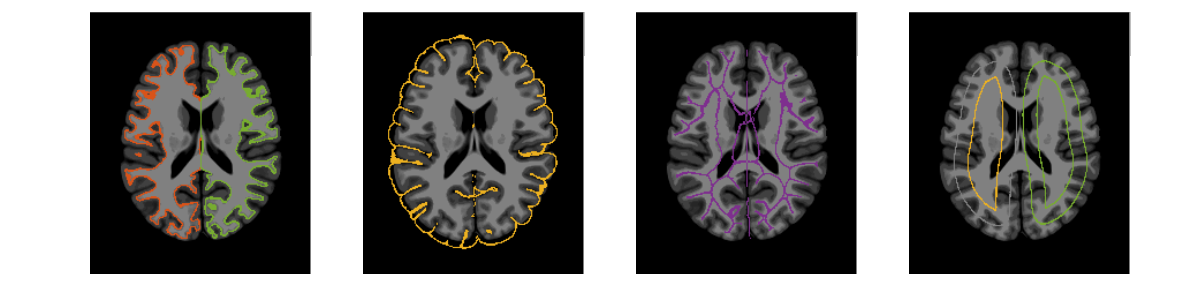

skind_pl = Surf_voxelise([surf_indL_pl,surf_indR_pl],'mode',0,'ref',mri_ind);
skind_plwarp = Surf_voxelise([surf_indL_plwarp,surf_indR_plwarp],'mode',0,'ref',mri_ind);
skind_pl_fill = Surf_voxelise([surf_indL_pl,surf_indR_pl],'mode',1,'ref',mri_ind);
skind_plwarp_fill = Surf_voxelise([surf_indL_plwarp,surf_indR_plwarp],'mode',1,'ref',mri_ind);

cmap = [gray(21)*0.5; imresize(lines(5),[39,3],'nearest')];
func_fuse = @(x,y) x.*(y==0)+y;

figure; lay_sub(1,4); next; plot_mri({func_fuse(mri_ind,3*skind.data),func_fuse(mri_ind,4*ismember(skind_pl.data,[1,3])), ...
    func_fuse(mri_ind,5*ismember(skind_pl.data,[2,4])),func_fuse(mri,2*skind_plwarp.data)},'off','enhance',10,'cmap',cmap,'act','z','cross_width',0);
lay_fig([12,3]); lay_linkview

warp_src = 'ind';

Vm = [vL_pl_iters{1}; vL_pl_iters{2}; vR_pl_iters{1}; vR_pl_iters{2}];
Vf = [vL_plwarp_iters{1}; vL_plwarp_iters{2}; vR_plwarp_iters{1}; vR_plwarp_iters{2}];
Vm = reshape(permute(Vm,[1,3,2]),[],3);
Vf = reshape(permute(Vf,[1,3,2]),[],3);

Vm = [Vm; surf_indL.Vertices; surf_indR.Vertices];
Vf = [Vf; surfL_warp.Vertices; surfR_warp.Vertices];
Vm = double(Vm); Vf = double(Vf);

sk_mask_sm = imgaussfilt3(single(skind.data),5) + skind_warp_fill.data >0;
sum(sk_mask_sm(:))

ans =      2580415


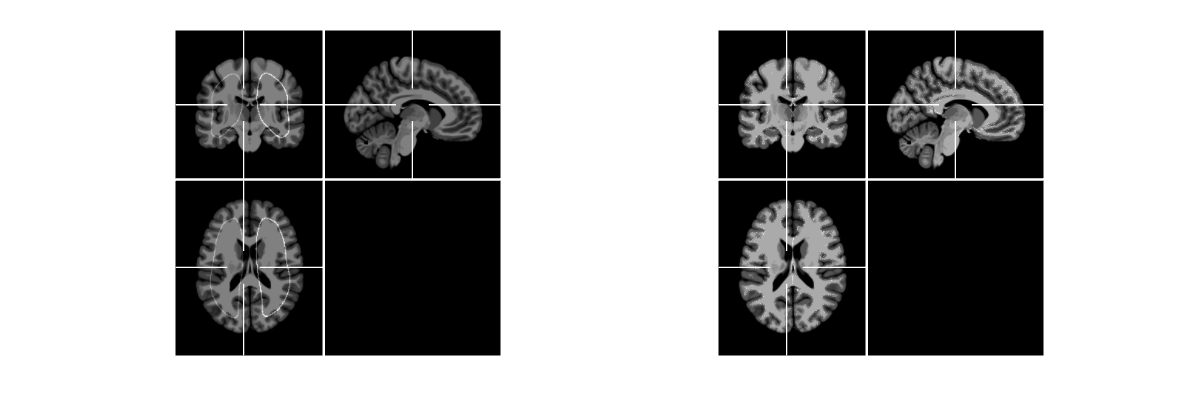


mnisz = mni_gray.size;
[X,Y,Z] = meshgrid(1:mnisz(2),1:mnisz(1),1:mnisz(3));
Vall = [X(:),Y(:),Z(:)];
Vm_ext = Vall(sk_mask_sm>0,:);

tic
interp_subj2flat_h = scatteredInterpolant(Vf,Vm,'linear','none');
switch warp_src
    case 'ind'
        mask = skind_warp.data;
    case 'mni'
        mask = skind.data;
end

Vout = round(interp_subj2flat_h(Vall(mask>0,:)));
idx = sub2ind(mnisz,Vout(:,2),Vout(:,1),Vout(:,3));
mask_new = single(mni_gray.data)*0;
mask_new(idx) = 1;

figure;
next; plot_mri({mask+mri_ind,mask_new+mri},'off','enhance',10)
lay_fig([12,4])

tic
Vout_ext = interp_subj2flat_h(Vm_ext);
toc

历时 4.160682 秒。


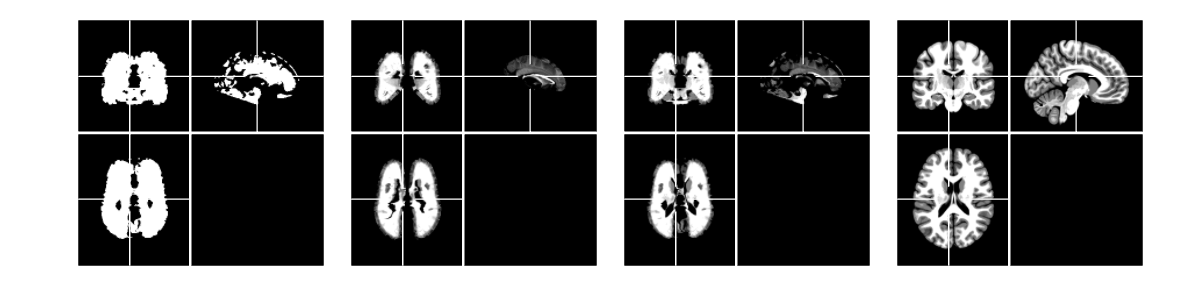

switch warp_src
    case 'ind'
        mri = mri_ind;
    case 'mni'
        mri = LAB;
end

tic
mask_full = getVol_vals(imgaussfilt3(mri,1)>0.01,Vout_ext,sk_mask_sm>0);
mask_warp = getVol_vals(mri>0.3,Vout_ext,sk_mask_sm>0);
mask_warp.data(isnan(mask_warp.data)) = 0;
mask_warp = medfilt3(single(mask_warp.data),[3,3,3]);
mask_warp = double(mask_warp>0.8);

sm_sz = 1;
if_sm = 1;

if if_sm
    Vout_extsm = Vout_ext;
    Vout_extsm(isnan(Vout_extsm)) = 0;
    Vall_new = Vall*0;
    Vall_new(sk_mask_sm>0,:) = Vout_extsm;
    XYZ = reshape(Vall_new,[mnisz,3]);
    mask_warpsm = smooth3(mask_warp,'box',sm_sz);
    for i = 1:3
        XYZ(:,:,:,i) = smooth3(XYZ(:,:,:,i).*mask_warp,'box',sm_sz)./(1e-6+mask_warpsm);
    end
    Vall_new = reshape(XYZ,[],3);
else
    Vout_extsm = Vout_ext;
end

temp = (skind_indist.data(:)/pl_d(1)).^4;
temp(temp>1) = 1;
Vall_new = Vall_new.*(1-temp) + Vall.*temp;
Vout_extsm = Vall_new(sk_mask_sm>0,:);

mri_warp = getVol_vals(mri,Vout_ext,sk_mask_sm>0);
mri_warp.data(mri_warp.data<0) = 0;
mri_warp.data = mri_warp.data.*(skind_plwarp_fill.data>0);

mri_warpsm = getVol_vals(mri,Vall_new,sk_mask_sm+1>0);
mask_warp = mask_warp + (skind_indist.data>pl_d(1))>0;
mri_warpsm.data = mri_warpsm.data.*imgaussfilt3(single(mask_warp),0.75);
mri_warpsm.data(mri_warpsm.data<0 | isnan(mri_warpsm.data)) = 0;

XYZ_mni2flat = reshape(Vall_new,[mnisz,3]);
XYZ_mni2flat = single(XYZ_mni2flat.*(skind_plwarp_fill.data>0));

figure; lay_sub(1,4)
next; plot_mri({mask_warp,mri_warp,mri_warpsm,mri_ind},'off','enhance',10); 
lay_fig([12,3]);


toc

历时 1.911443 秒。


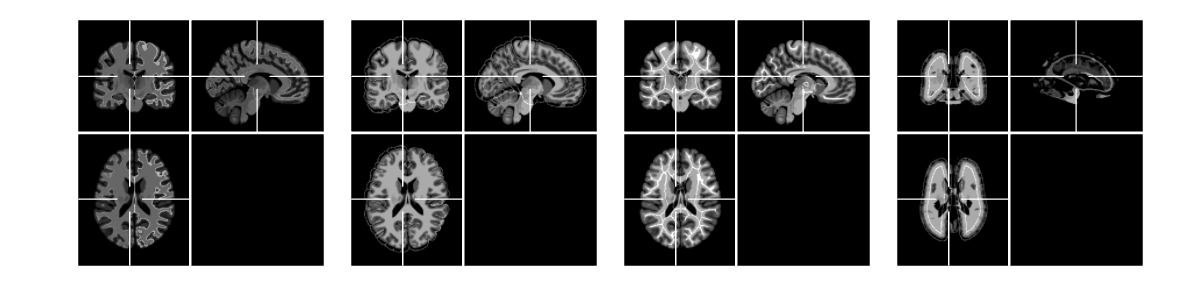

figure; lay_sub(1,4); next; plot_mri({mri_ind+skind.data,mri_ind+ismember(skind_pl.data,[1,3]), ...
    mri_ind+ismember(skind_pl.data,[2,4]),mri_warpsm.data+(skind_plwarp.data>0)},'off','enhance',10);
lay_fig([12,3]); lay_linkview

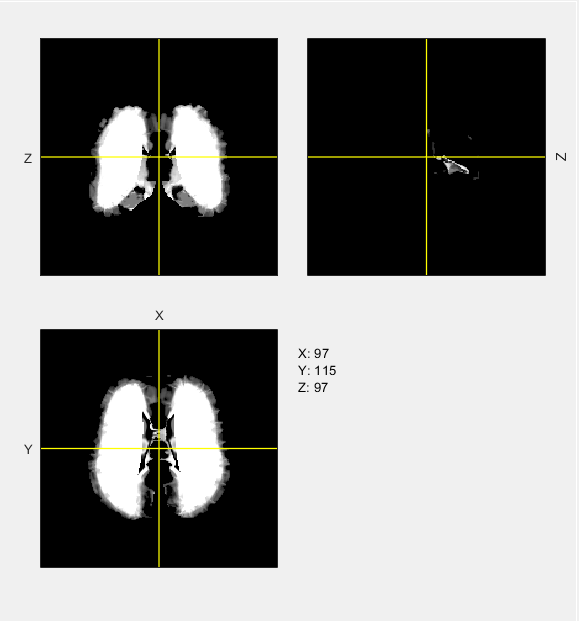

mask_out = imgaussfilt3(skoutsm_fill.data,4)>0;
mask_out = imgaussfilt3(single(mask_out),0.25);

mni_frac_inflat = mri_warpsm.data.*mask_out;
mni_frac_inflat(skind_warp_dist>4) = 2;
mni_inflat = mni_frac_inflat;

plot_mri(mni_frac_inflat)

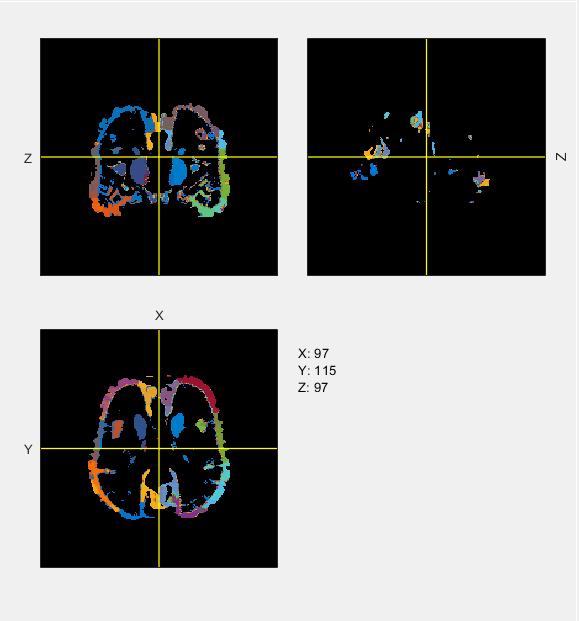

lab_warpsm = getVol_vals(HCPex,Vall_new,sk_mask_sm+1>0);
plot_mri(lab_warpsm,'pos',[51,124,84]); colormap(cmap_disc)

error

错误使用 error
输入参数的数目不足。

mri = mni_inflat;
% mri = map_L1sum{2};
% mri = map_L1sum{5};

% mri = map_L1sum{2}.^2 - map_L2sum{2};

tic
maskinv = skind.data;
sk_maskinv_sm = imgaussfilt3(single(maskinv),4)>0;
sum(sk_maskinv_sm(:))

ans =      2281489



mnisz = mni_gray.size;
[X,Y,Z] = meshgrid(1:mnisz(2),1:mnisz(1),1:mnisz(3));
Vall = [X(:),Y(:),Z(:)];

Vm_extinv = Vall(sk_maskinv_sm>0,:);
interp_flat2subj_h = scatteredInterpolant(Vm,Vf,'linear','none');

Vout_extinv = interp_flat2subj_h(Vm_extinv);
idx_extinv = sk_maskinv_sm>0;

mri_warpinv = getVol_vals(mri,Vout_extinv,idx_extinv);
mri_warpinv.data(mri_warpinv.data<0 | isnan(mri_warpinv.data)) = 0;
mri_warpinv.data = mri_warpinv.data.*(skind_pl_fill.data>0);

Vall_new = Vall*0;
Vall_new(sk_maskinv_sm>0,:) = Vout_extinv;
XYZ_flat2mni = reshape(Vall_new,[mnisz,3]);
XYZ_flat2mni = single(XYZ_flat2mni.*(skind_pl_fill.data>0));
toc

历时 17.156247 秒。


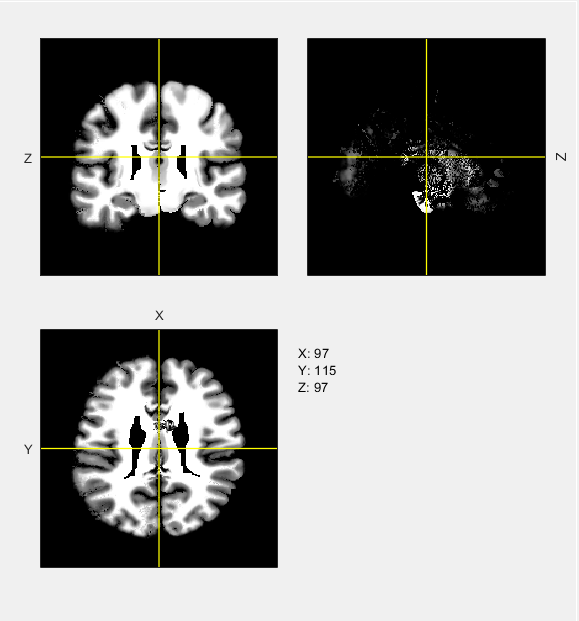


plot_mri(mri_warpinv)

tic
mri = mri_warpinv;
[mri_tex3D,mri_Ren3D,~,mri_depth3D] = Pilo_gen(mri,'XYZ',mni_XYZ8c,'Nxy',k*divN,'Nz',[],'tex_lim',{'1','99',1.5}, ...
    'alpha_list',[1,0.25],'proj_func',[],'proj_view','out');
toc


plot_pilos(mni_XYZfi,mri_Ren3D,[],'depth3D',mri_depth3D.data*0);

# Save results

mniL_pl = surf_indL_pl;
mniL_inflat_pl = surf_indL_plwarp;
mniR_pl = surf_indR_pl;
mniR_inflat_pl = surf_indR_plwarp;

save([save_dir,'mni_frac_inflat.mat'],'mni_frac_inflat','mniL_inflat','mniR_inflat', ...
    'mniL_pl','mniL_inflat_pl','mniR_pl','mniR_inflat_pl','pl_d','pl_iter')

MRI_save_File(XYZ_flat2mni,[save_dir,'XYZ_flat2mni.nii.gz'],'info',mni_gray)
MRI_save_File(XYZ_mni2flat,[save_dir,'XYZ_mni2flat.nii.gz'])

[Gx,Gy,Gz] = imgradientxyz(skind_warp_dist);
Gx = imgaussfilt3(Gx,2);
Gy = imgaussfilt3(Gy,2);
Gz = imgaussfilt3(Gz,2);
temp = 1e-6+sqrt(Gx.^2+Gy.^2+Gz.^2);
G = [Gx(:),Gy(:),Gz(:)]./temp(:);

nb_d = 1;
[Y,X,Z] = ndgrid(-nb_d:nb_d);
v = [X(:),Y(:),Z(:)];
v = (v./vecnorm(v,2,2))';
% 点到平面距离通过向量点积来计算（余弦定理）
w = sqrt(1 - (G(:,1).*v(1,:)+G(:,2).*v(2,:)+G(:,3).*v(3,:)).^2);
w(:,(end+1)/2) = 1;
w = real(w.^6);
w = w./sum(w,2);
% 检查w合不合理
% id = sub2ind(size(Gx),98,45,97); temp = amp(reshape(w(id,:),[3,3,3]),0)

idx = reshape(1:size(w,1),size(temp));
idx = idx(1:2*nb_d+1,1:2*nb_d+1,1:2*nb_d+1);
idx = idx(:) - idx(nb_d+1,nb_d+1,nb_d+1);
idx_mat = repmat((1:size(w,1))',1,(2*nb_d+1)^3);

for i = 1:(2*nb_d+1)^3
    idx_mat(:,i) = circshift(idx_mat(:,i),-idx(i));
end

% 检查idx_mat正确性
% temp = mri_inflat(idx_mat); id = reshape(1:27,[3,3,3]); plot_mri(reshape(temp(:,id(2,2,2)),size(mri_inflat)) - reshape(temp(:,id(2,3,2)),size(mri_inflat)))
% plot_mri(mri_inflat - circshift(mri_inflat,-2,2))

tic
val = mni_frac_inflat(:);
for i = 1:2
    val = sum(val(idx_mat).*w,2);
end
mri_inflat_sm = reshape(val,size(mni_frac_inflat));
toc

plot_mri(mri_inflat_sm)

disp_toc(t_tic)
error

tic
mri = mri_warpsm.data.*mask_out;
[mri_tex3D,mri_Ren3D,~,mri_depth3D] = Pilo_gen(mri,'XYZ',mni_XYZ8c,'Nxy',k*divN,'Nz',[],'tex_lim',{'1','99',1.5}, ...
    'alpha_list',[1,0.25],'proj_func',[],'proj_view','out');
toc

plot_pilos(mni_XYZfi,mri_Ren3D,[],'depth3D',mri_depth3D.data*40);

switch warp_src
    case 'ind'
        mask = skind_warp.data;
    case 'mni'
        mask = skind.data;
end

Vout = round(interp_subj2flat_h(Vall(mask>0,:)));
idx = sub2ind(mnisz,Vout(:,2),Vout(:,1),Vout(:,3));
mask_new = mni_gray.data*0;
mask_new(idx) = 1;

figure; lay_sub(1,4)
next; plot_mri({mask+mri_ind.data,mask_new,mask+mri_warpsm.data,mask_new+mri},'off')
lay_fig([12,3])

function val_new = interp_sph(v,val_raw,v_q)
[TH,PHI] = cart2sph(v(:,1),v(:,2),v(:,3));
[TH_q,PHI_q] = cart2sph(v_q(:,1),v_q(:,2),v_q(:,3));

val_new = [];
for i = 1:2
    rot_TH = pi*(i-1);
    th = mod(TH+rot_TH,2*pi);
    th_q = mod(TH_q+rot_TH,2*pi);

    vv_in = [th,PHI];
    vv_q = [th_q,PHI_q];

    for j = 1:size(val_raw,2)
        interp_h = scatteredInterpolant(vv_in,val_raw(:,j));
        val_new(:,j,i) = interp_h(vv_q);
    end
end
w = 1 - abs(mod(TH_q,2*pi)/pi - 1);
w = permute(w,[1,3,2]);
val_new = val_new(:,:,1).*w + val_new(:,:,2).*(1-w);
end

function [K1] = get_reduce_curvK1(surf_raw,bin,sph_v)
[surf_rd1, idx_rd] = Surf_func_ROI(surf_raw,'reduce','bin',bin,'get_idx',1);
surf_rd2 = surf_rd1; surf_rd2.Vertices = surf_raw.Vertices(idx_rd,:);
val_curv = Surf_func_Val(surf_rd2,'curvature','fine',0);
v_q = sph_v; v = v_q(idx_rd,:);
% K1 = val_curv.k1; K2 = val_curv.k2;
% K = interp_sph(v,[K1,K2],v_q);
% K1 = K(:,1); K2 = K(:,2);
K1 = interp_sph(v,val_curv.k1,v_q);
end

function val = surf_valsmooth(surf_in,val,sm_iter)
temp = surf_in; temp.Vertices(:,1:size(val,2)) = val;
temp = Surf_smooth(temp,'iter',sm_iter,'type',3);
val = temp.Vertices(:,1:size(val,2));
end

function eigenmodes = get_surfEigmode(surf_raw,num_modes)
PWD = pwd;
brainEigmode_dir = 'E:\work_Code\Matlab\from_github\BrainEigenmodes-main\';
cd(brainEigmode_dir)
data_dir = 'data\test_data_zys/';
surface_interest = 'zys';
hemisphere = 'lh';
mesh_interest = 'white';

% num_modes = 10;

surface_input_filename = sprintf('%s/%s_%s-%s.vtk', data_dir,surface_interest, mesh_interest, hemisphere);
% mask_filename = sprintf('data/template_surfaces_volumes/%s_cortex-%s_mask.txt', surface_interest, hemisphere);
output_eval_filename = sprintf('%s/%s_%s-%s_eval_%i.txt',data_dir,surface_interest, mesh_interest, hemisphere, num_modes);
output_emode_filename = sprintf('%s/%s_%s-%s_emode_%i.txt',data_dir,surface_interest, mesh_interest, hemisphere, num_modes);

Surf_save_File(surf_raw,surface_input_filename);

tic
cmd_str = [];
cmd_str{1} = 'CALL conda.bat activate pytorch3d';
cmd_str{end+1,1} = ['python surface_eigenmodes.py ',surface_input_filename,' ',output_eval_filename,' ',output_emode_filename,' -save_cut 0 -N ',num2str(num_modes),' -is_mask 0'];
bat_name = 'test1.bat';
writecell(cmd_str,bat_name,'FileType','text')
system(bat_name);
toc

eigenmodes = dlmread(output_emode_filename);
cd(PWD)
end

function [disk_img,Vnew] = sph2disk(cur_sph,val_disk,texN,if_plot)
surf_disk = cur_sph;
v = surf_disk.Vertices;
[TH,PHI] = cart2sph(v(:,3),v(:,2),v(:,1));
PHI = PHI+pi/2;
Vnew = [cos(TH).*PHI,sin(TH).*PHI];

x = linspace(-pi,pi,texN);
[Y,X] = ndgrid(x);

interp_h = scatteredInterpolant(Vnew,val_disk);
val_new = interp_h([X(:),Y(:)]);
disk_img = reshape(val_new,texN,[]);

if if_plot
    Vplot = Vnew;
    Vplot(PHI>pi*0.95,:) = NaN; Vplot(:,3) = 0;
    surf_disk.Vertices = Vplot;

    figure;
    next; plot_surf(surf_disk,'colors',val_disk); next; showc(disk_img); axis xy
    lay_fig([12,3]); colormap jet
end
end

function img = scatteredInterpolant_img(v,val,lim_max,img_sz)
x = linspace(0,lim_max(2),img_sz(2)); y = linspace(0,lim_max(1),img_sz(1));
[X,Y] = meshgrid(x,y);
interp_fmni = scatteredInterpolant(v,val);
img = interp_fmni([X(:),Y(:)]);
img = reshape(img,img_sz);
end

function def_weight = make_maskWeight(def_sz,fix_bnd_sz,gamma)
def_weight = ones(round(def_sz([1,2])/4));
def_weight = imfilter(def_weight,fspecial('average',fix_bnd_sz));
def_weight = imresize(def_weight,def_sz([1,2]));
def_weight = amp(def_weight,0).^gamma;
end

function mri_warp = getVol_vals(mri_src,V,idx)
if isnumeric(mri_src)
    mri_src = single(mri_src);
end
mri_src = MRI_read_Data(mri_src);
temp = MRI_func_ROI(mri_src,'sample',V,'method',1);
mri_warp = mri_src; mri_warp.data(:) = 0;
mri_warp.data(idx) = temp;
end